%{
radial clearance
axial clearance
coil h
coil r in
coil r out
wire diameter
coil former radial t
coil former axial t
mag bot axial t
mag top axial t
armature r
chamfer r
chamfer h
shell t
packing ratio
current safety factor
air gap
relative permeability
permeability
copper wire current capacity
%}
close all
clear
syms c_r c_a h_C r_Cout D_w t_cfr t_cfa t_mba t_mta...
    r_A r_cham h_cham t_shell PR CSF h_air mu mu0 CWCC I

magnetic_top_r = t_shell + r_Cout + c_r

$$magnetic\_top\_r = c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}$$

r_Cin = r_A + c_r + t_cfr

$$r\_Cin = c_{r}+r_{A}+t_{\mathrm{cfr}}$$

R_path1 = r_Cout / (mu * mu0 * t_mta * pi * 0.25 * (magnetic_top_r + r_Cout + c_a))

$$R\_path1 = \frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu_{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}$$

h_coilformer = h_C + 2 * t_cfa

$$h\_coilformer = h_{C}+2\,t_{\mathrm{cfa}}$$

shell_rin = r_Cout + c_r

$$shell\_rin = c_{r}+r_{\mathrm{Cout}}$$

shell_rout = magnetic_top_r

$$shell\_rout = c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}$$

R_path2_a = (t_mta + h_coilformer + t_mba / 2 - c_a) /...
    (mu * mu0 * pi * (magnetic_top_r^2 - shell_rin^2))

$$R\_path2\_a = \frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\left({\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\right)}$$

    
R_path2_b = c_a / (mu0 *pi * (magnetic_top_r^2 - shell_rin^2))

$$R\_path2\_b = \frac{c_{a}}{\mu_{0}\,\pi \,\left({\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\right)}$$

R_path2 = R_path2_a + R_path2_b

$$R\_path2 = \frac{c_{a}}{\mu_{0}\,\pi \,\left({\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\right)}+\frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\left({\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\right)}$$

R_path3_a = 0.5 * t_shell /...
    (mu * mu0 * t_mba * pi * (shell_rin + t_shell * 0.5))

$$R\_path3\_a = \frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}$$

R_path3_b = c_r / (mu0 * t_mba * pi * (shell_rin - 0.5 * c_r))

$$R\_path3\_b = \frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}$$

R_path3_c = (r_Cout - (r_A + c_r)) /...
        (mu * mu0 * t_mba * pi * 0.5 * ((r_A + c_r) + r_Cout))

$$R\_path3\_c = -\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}$$

R_path3_d = c_r / (mu0 * t_mba * pi * (r_A + 0.5 * c_r))

$$R\_path3\_d = \frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}$$

R_path3_e = r_A / (mu * mu0 * t_mba * pi * 0.5 * r_A)

$$R\_path3\_e = \frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }$$


R_path3 = R_path3_a + R_path3_b + R_path3_c + R_path3_d + R_path3_e

$$R\_path3 = \frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}+\frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}-\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}$$

theta = atan(h_cham / (r_A - r_cham))

$$theta = \mathrm{atan}\left(\frac{h_{\mathrm{cham}}}{r_{A}-r_{\mathrm{cham}}}\right)$$

R_path4_a = (0.5 * (h_coilformer + t_mba) + c_a - h_air) /...
    (mu * mu0 * pi * r_A^2)

$$R\_path4\_a = \frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi }$$

R_path4_b_1 = h_air / (mu0 * pi * r_cham^2)

$$R\_path4\_b\_1 = \frac{h_{\mathrm{air}}}{\mu_{0}\,{r_{\mathrm{cham}}}^{2}\,\pi }$$

R_path4_b_2 = (h_air * cos(theta)) / (mu0 * pi * (r_A^2 - r_cham^2)/cos(theta))

$$R\_path4\_b\_2 = \frac{h_{\mathrm{air}}}{\mu_{0}\,\pi \,\left({r_{A}}^{2}-{r_{\mathrm{cham}}}^{2}\right)\,\left(\frac{{h_{\mathrm{cham}}}^{2}}{{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}+1\right)}$$

R_path4_b = 1 / (1/R_path4_b_1 + 1/R_path4_b_2)

$$R\_path4\_b = \frac{1}{\frac{\pi \,\mu_{0}\,{r_{\mathrm{cham}}}^{2}}{h_{\mathrm{air}}}+\frac{\pi \,\mu_{0}\,\left({r_{A}}^{2}-{r_{\mathrm{cham}}}^{2}\right)\,\left(\frac{{h_{\mathrm{cham}}}^{2}}{{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}+1\right)}{h_{\mathrm{air}}}}$$

R_path4_c = (0.5 * (h_coilformer + t_mta) + c_a) /...
    (mu * mu0 * pi * r_A^2)

$$R\_path4\_c = \frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi }$$

R_path4 = R_path4_a + R_path4_b + R_path4_c

$$R\_path4 = \frac{1}{\frac{\pi \,\mu_{0}\,{r_{\mathrm{cham}}}^{2}}{h_{\mathrm{air}}}+\frac{\pi \,\mu_{0}\,\left({r_{A}}^{2}-{r_{\mathrm{cham}}}^{2}\right)\,\left(\frac{{h_{\mathrm{cham}}}^{2}}{{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}+1\right)}{h_{\mathrm{air}}}}+\frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi }+\frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi }$$

R_total = R_path1 + R_path2 + R_path3 + R_path4

$$R\_total = \begin{array}{l} \frac{1}{\frac{\pi \,\mu_{0}\,{r_{\mathrm{cham}}}^{2}}{h_{\mathrm{air}}}+\frac{\pi \,\mu_{0}\,\left({r_{A}}^{2}-{r_{\mathrm{cham}}}^{2}\right)\,\left(\frac{{h_{\mathrm{cham}}}^{2}}{{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}+1\right)}{h_{\mathrm{air}}}}+\frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }+\frac{c_{a}}{\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}+\frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\sigma_{2}}+\frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\sigma_{2}}+\frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}-\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}+\frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu_{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}\\ \mathrm{where}\\ \sigma_{1}={\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\\ \sigma_{2}=\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi \end{array}$$

func_R_total = matlabFunction(R_total)

func_R_total = function_handle with value:
    @(c_a,c_r,h_C,h_air,h_cham,mu,mu0,r_A,r_Cout,r_cham,t_cfa,t_mba,t_mta,t_shell)1.0./((mu0.*r_cham.^2.*pi)./h_air+(mu0.*pi.*(r_A.^2-r_cham.^2).*(h_cham.^2.*1.0./(r_A-r_cham).^2+1.0))./h_air)+2.0./(mu.*mu0.*t_mba.*pi)+c_a./(mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_A))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_Cout))+(-c_a+h_C+t_cfa.*2.0+t_mba./2.0+t_mta)./(mu.*mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+(1.0./r_A.^2.*(c_a+h_C./2.0-h_air+t_cfa+t_mba./2.0))./(mu.*mu0.*pi)+(1.0./r_A.^2.*(c_a+h_C./2.0+t_cfa+t_mta./2.0))./(mu.*mu0.*pi)+t_shell./(mu.*mu0.*t_mba.*pi.*(c_r+r_Cout+t_shell./2.0).*2.0)-((c_r+r_A-r_Cout).*2.0)./(mu.*mu0.*t_mba.*pi.*(c_r+r_A+r_Cout))+(r_Cout.*4.0)./(mu.*mu0.*t_mta.*pi.*(c_a+c_r+r_Cout.*2.0+t_shell))


A_w = D_w^2 * pi * 0.25

$$A\_w = \frac{\pi \,{D_{w}}^{2}}{4}$$

N = floor(h_C/D_w) * floor((r_Cout - r_Cin)/D_w) * PR

$$N = \mathrm{PR}\,\left\lfloor \frac{h_{C}}{D_{w}}\right\rfloor \,\left\lfloor -\frac{c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}}{D_{w}}\right\rfloor$$

func_N = matlabFunction(N)

func_N = function_handle with value:
    @(D_w,PR,c_r,h_C,r_A,r_Cout,t_cfr)PR.*floor(h_C./D_w).*floor(-(c_r+r_A-r_Cout+t_cfr)./D_w)


I_max = CWCC * A_w * CSF

$$I\_max = \frac{\pi \,\mathrm{CSF}\,\mathrm{CWCC}\,{D_{w}}^{2}}{4}$$

func_I_max = matlabFunction(I_max)

func_I_max = function_handle with value:
    @(CSF,CWCC,D_w)(CSF.*CWCC.*D_w.^2.*pi)./4.0


func_I_max(0.8,10E6,0.26E-3)

ans = 0.4247

NI = N * I

$$NI = \text{I}\,\mathrm{PR}\,\left\lfloor \frac{h_{C}}{D_{w}}\right\rfloor \,\left\lfloor -\frac{c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}}{D_{w}}\right\rfloor$$

double(subs(NI,...
    [D_w,    I,                           PR,  c_r,    h_C,  r_A,    r_Cout,t_cfr],...
    [0.26E-3,func_I_max(0.8,10E6,0.26E-3),0.95,0.05E-3,50E-3,4.95E-3,15E-3, 1.5E-3]))

ans = 2.4791e+03

phi = NI / R_total

$$phi = \begin{array}{l} \frac{\text{I}\,\mathrm{PR}\,\left\lfloor \frac{h_{C}}{D_{w}}\right\rfloor \,\left\lfloor -\frac{c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}}{D_{w}}\right\rfloor }{\frac{1}{\frac{\pi \,\mu_{0}\,{r_{\mathrm{cham}}}^{2}}{h_{\mathrm{air}}}+\frac{\pi \,\mu_{0}\,\left({r_{A}}^{2}-{r_{\mathrm{cham}}}^{2}\right)\,\left(\frac{{h_{\mathrm{cham}}}^{2}}{{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}+1\right)}{h_{\mathrm{air}}}}+\frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }+\frac{c_{a}}{\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}+\frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\sigma_{2}}+\frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\sigma_{2}}+\frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}-\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}+\frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu_{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}}\\ \mathrm{where}\\ \sigma_{1}={\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\\ \sigma_{2}=\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi \end{array}$$

func_phi = matlabFunction(phi)

func_phi = function_handle with value:
    @(D_w,I,PR,c_a,c_r,h_C,h_air,h_cham,mu,mu0,r_A,r_Cout,r_cham,t_cfa,t_cfr,t_mba,t_mta,t_shell)(I.*PR.*floor(h_C./D_w).*floor(-(c_r+r_A-r_Cout+t_cfr)./D_w))./(1.0./((mu0.*r_cham.^2.*pi)./h_air+(mu0.*pi.*(r_A.^2-r_cham.^2).*(h_cham.^2.*1.0./(r_A-r_cham).^2+1.0))./h_air)+2.0./(mu.*mu0.*t_mba.*pi)+c_a./(mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_A))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_Cout))+(-c_a+h_C+t_cfa.*2.0+t_mba./2.0+t_mta)./(mu.*mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+(1.0./r_A.^2.*(c_a+h_C./2.0-h_air+t_cfa+t_mba./2.0))./(mu.*mu0.*pi)+(1.0./r_A.^2.*(c_a+h_C./2.0+t_cfa+t_mta./2.0))./(mu.*mu0.*pi)+t_shell./(mu.*mu0.*t_mba.*pi.*(c_r+r_Cout+t_shell./2.0).*2.0)-((c_r+r_A-r_Cout).*2.0)./(mu.*mu0.*t_mba.*pi.*(c_r+r_A+r_Cout))+(r_Cout.*4.0)./(mu.*mu0.*t_mta.*pi.*(c_a+c_r+r_Cout.*2.0+t_shell)))


Fmag_1 = 0.5 * (phi * R_path4_b_2/(R_path4_b_1 + R_path4_b_2))^2 /...
    (mu0 * pi * r_cham^2)

$$Fmag\_1 = \begin{array}{l} \frac{{\text{I}}^{2}\,{\mathrm{PR}}^{2}\,{h_{\mathrm{air}}}^{2}\,{\left\lfloor \frac{h_{C}}{D_{w}}\right\rfloor }^{2}\,{\left\lfloor -\frac{c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}}{D_{w}}\right\rfloor }^{2}}{2\,{\mu_{0}}^{3}\,{r_{\mathrm{cham}}}^{2}\,\pi^{3}\,{\sigma_{2}}^{2}\,{\left(\frac{h_{\mathrm{air}}}{\mu_{0}\,{r_{\mathrm{cham}}}^{2}\,\pi }+\frac{h_{\mathrm{air}}}{\mu_{0}\,\pi \,\sigma_{2}\,\sigma_{1}}\right)}^{2}\,{\sigma_{1}}^{2}\,{\left(\frac{1}{\frac{\pi \,\mu_{0}\,{r_{\mathrm{cham}}}^{2}}{h_{\mathrm{air}}}+\frac{\pi \,\mu_{0}\,\sigma_{2}\,\sigma_{1}}{h_{\mathrm{air}}}}+\frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }+\frac{c_{a}}{\mu_{0}\,\pi \,\sigma_{3}}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}+\frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\sigma_{3}}+\frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\sigma_{4}}+\frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\sigma_{4}}+\frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}-\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}+\frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu_{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\frac{{h_{\mathrm{cham}}}^{2}}{{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}+1\\ \sigma_{2}={r_{A}}^{2}-{r_{\mathrm{cham}}}^{2}\\ \sigma_{3}={\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\\ \sigma_{4}=\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi \end{array}$$

Fmag_2 = 0.5 * cos(theta) * (phi * R_path4_b_1/(R_path4_b_1 + R_path4_b_2))^2 /...
    (mu0 * pi * (r_A^2 - r_cham^2)/cos(theta))

$$Fmag\_2 = \begin{array}{l} \frac{{\text{I}}^{2}\,{\mathrm{PR}}^{2}\,{h_{\mathrm{air}}}^{2}\,{\left\lfloor \frac{h_{C}}{D_{w}}\right\rfloor }^{2}\,{\left\lfloor -\frac{c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}}{D_{w}}\right\rfloor }^{2}}{2\,{\mu_{0}}^{3}\,{r_{\mathrm{cham}}}^{4}\,\pi^{3}\,\sigma_{2}\,{\left(\frac{h_{\mathrm{air}}}{\mu_{0}\,{r_{\mathrm{cham}}}^{2}\,\pi }+\frac{h_{\mathrm{air}}}{\mu_{0}\,\pi \,\sigma_{2}\,\sigma_{1}}\right)}^{2}\,\sigma_{1}\,{\left(\frac{1}{\frac{\pi \,\mu_{0}\,{r_{\mathrm{cham}}}^{2}}{h_{\mathrm{air}}}+\frac{\pi \,\mu_{0}\,\sigma_{2}\,\sigma_{1}}{h_{\mathrm{air}}}}+\frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }+\frac{c_{a}}{\mu_{0}\,\pi \,\sigma_{3}}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}+\frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\sigma_{3}}+\frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\sigma_{4}}+\frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\sigma_{4}}+\frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}-\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}+\frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu_{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\frac{{h_{\mathrm{cham}}}^{2}}{{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}+1\\ \sigma_{2}={r_{A}}^{2}-{r_{\mathrm{cham}}}^{2}\\ \sigma_{3}={\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\\ \sigma_{4}=\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi \end{array}$$

Fmag = Fmag_1 + Fmag_2

func_Fmag = matlabFunction(Fmag)

func_Fmag = function_handle with value:
    @(D_w,I,PR,c_a,c_r,h_C,h_air,h_cham,mu,mu0,r_A,r_Cout,r_cham,t_cfa,t_cfr,t_mba,t_mta,t_shell)(I.^2.*PR.^2.*h_air.^2.*1.0./mu0.^3.*1.0./r_cham.^2.*1.0./pi.^3.*floor(h_C./D_w).^2.*floor(-(c_r+r_A-r_Cout+t_cfr)./D_w).^2.*1.0./(r_A.^2-r_cham.^2).^2.*1.0./((h_air.*1.0./r_cham.^2)./(mu0.*pi)+h_air./(mu0.*pi.*(r_A.^2-r_cham.^2).*(h_cham.^2.*1.0./(r_A-r_cham).^2+1.0))).^2.*1.0./(h_cham.^2.*1.0./(r_A-r_cham).^2+1.0).^2.*1.0./(1.0./((mu0.*r_cham.^2.*pi)./h_air+(mu0.*pi.*(r_A.^2-r_cham.^2).*(h_cham.^2.*1.0./(r_A-r_cham).^2+1.0))./h_air)+2.0./(mu.*mu0.*t_mba.*pi)+c_a./(mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_A))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_Cout))+(-c_a+h_C+t_cfa.*2.0+t_mba./2.0+t_mta)./(mu.*mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+(1.0./r_A.^2.*(c_a+h_C./2.0-h_air+t_cfa+t_mba./2.0))./(mu.*mu0.*pi)+(1.0./r_A.^2.*(c_a+h_C./2.0+t_cfa+t_mta./2.0))./(mu.*mu0.*pi)+t_shell./(mu.*mu0.*t_mba.*pi.*(c_r

%var5 = gradient(Fmag)


%[var_r_cham,var_h_cham] = meshgrid((1:0.05:3)*1E-3,(1:0.05:3)*1E-3);

%r = func_Fmag(...
%    ...[CSF,CWCC,D_w,    PR, c_a,    c_r,    h_C,  h_air,h_cham,    mu, mu0,             r_A, r_Cout,r_cham,    t_cfa,t_cfr, t_mba,t_mta,t_shell]
%        0.9,10E6,0.26E-3,0.9,0.05E-3,0.05E-3,50E-3,1E-3, var_h_cham,850,1.25663706212E-6,5E-3,12E-3, var_r_cham,4E-3, 1.5E-3,4E-3, 4E-3, 2E-3   );
%surf(var_r_cham,var_h_cham,r)

p1 = double(subs(R_path1,...
    [c_a,    c_r,    mu, mu0,             r_Cout,t_mta,t_shell],...
    [0.05E-3,0.05E-3,850,1.25663706212E-3,22E-3, 4E-3, 2.4E-3 ]))

p1 = 1.3494e+05

p2 =double(subs(R_path2,...
    [c_a,    c_r,    h_C,  mu, mu0,             r_Cout,t_cfa,t_mba,t_mta,t_shell],...
    [0.05E-3,0.05E-3,50E-3,850,1.25663706212E-3,22E-3, 4E-3, 4E-3 ,4E-3 ,2.4E-3 ]))

p2 = 4.9878e+05

p3 = double(subs(R_path3,...
    [c_r,    mu, mu0,             r_A,   r_Cout,t_mba,t_shell],...
    [0.05E-3,850,1.25663706212E-6,4.9E-3,12E-3, 4E-3 ,2.4E-3 ]))

p3 = 1.1239e+06

p4 = double(subs(R_path4,...
    [c_a,    h_C,  h_air,h_cham,mu, mu0,             r_A,   r_cham,t_cfa,t_mba,t_mta],...
    [0.05E-3,50E-3,1E-3, 3E-3,  850,1.25663706212E-6,4.9E-3,4E-3,  4E-3, 4E-3, 4E-3 ]))

p4 = 2.9998e+06

p4_1 = double(subs(R_path4_b_1,...
    [h_air,mu0,             r_cham],...
    [1E-3, 1.25663706212E-6,4E-3  ]))

p4_1 = 1.5831e+07

p4_2 = double(subs(R_path4_b_2,...
    [h_air,h_cham,mu0,             r_A,   r_cham],...
    [1E-3, 3E-3,  1.25663706212E-6,4.9E-3,4E-3  ]))

p4_2 = 2.6111e+06

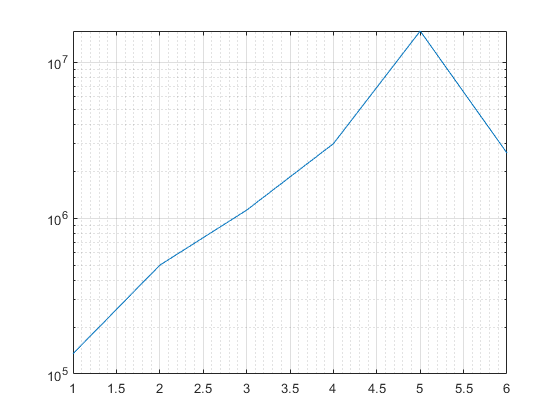

semilogy([p1,p2,p3,p4,p4_1,p4_2]),grid minor,grid on

%{
double(subs(phi,...
    [CSF, CWCC,D_w,    PR, c_a,    c_r,    h_C,  h_air,h_cham,mu, mu0,             r_A, r_Cout,r_cham,t_cfa,t_cfr, t_mba,t_mta,t_shell],...
    [0.75,10E6,0.26E-3,0.8,0.05E-3,0.05E-3,25E-3,1E-3, 1E-3,  850,1.25663706212E-6,5E-3,12E-3, 1E-3,  4E-3, 1.5E-3, 4E-3, 4E-3, 2E-3   ]))
double(subs(Fmag_1,...
    [CSF, CWCC,D_w,    PR, c_a,    c_r,    h_C,  h_air,h_cham,mu, mu0,             r_A, r_Cout,r_cham,t_cfa,t_cfr, t_mba,t_mta,t_shell],...
    [0.75,10E6,0.26E-3,0.8,0.05E-3,0.05E-3,25E-3,1E-3, 1E-3,  850,1.25663706212E-6,5E-3,12E-3, 1E-3,  4E-3, 1.5E-3, 4E-3, 4E-3, 2E-3   ]))
%}


L = N * phi / I

$$L = \begin{array}{l} \frac{{\mathrm{PR}}^{2}\,{\left\lfloor \frac{h_{C}}{D_{w}}\right\rfloor }^{2}\,{\left\lfloor -\frac{c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}}{D_{w}}\right\rfloor }^{2}}{\frac{1}{\frac{\pi \,\mu_{0}\,{r_{\mathrm{cham}}}^{2}}{h_{\mathrm{air}}}+\frac{\pi \,\mu_{0}\,\left({r_{A}}^{2}-{r_{\mathrm{cham}}}^{2}\right)\,\left(\frac{{h_{\mathrm{cham}}}^{2}}{{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}+1\right)}{h_{\mathrm{air}}}}+\frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }+\frac{c_{a}}{\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}+\frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\sigma_{2}}+\frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\sigma_{2}}+\frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}-\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}+\frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu_{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}}\\ \mathrm{where}\\ \sigma_{1}={\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\\ \sigma_{2}=\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi \end{array}$$

func_L = matlabFunction(L)

func_L = function_handle with value:
    @(D_w,PR,c_a,c_r,h_C,h_air,h_cham,mu,mu0,r_A,r_Cout,r_cham,t_cfa,t_cfr,t_mba,t_mta,t_shell)(PR.^2.*floor(h_C./D_w).^2.*floor(-(c_r+r_A-r_Cout+t_cfr)./D_w).^2)./(1.0./((mu0.*r_cham.^2.*pi)./h_air+(mu0.*pi.*(r_A.^2-r_cham.^2).*(h_cham.^2.*1.0./(r_A-r_cham).^2+1.0))./h_air)+2.0./(mu.*mu0.*t_mba.*pi)+c_a./(mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_A))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_Cout))+(-c_a+h_C+t_cfa.*2.0+t_mba./2.0+t_mta)./(mu.*mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+(1.0./r_A.^2.*(c_a+h_C./2.0-h_air+t_cfa+t_mba./2.0))./(mu.*mu0.*pi)+(1.0./r_A.^2.*(c_a+h_C./2.0+t_cfa+t_mta./2.0))./(mu.*mu0.*pi)+t_shell./(mu.*mu0.*t_mba.*pi.*(c_r+r_Cout+t_shell./2.0).*2.0)-((c_r+r_A-r_Cout).*2.0)./(mu.*mu0.*t_mba.*pi.*(c_r+r_A+r_Cout))+(r_Cout.*4.0)./(mu.*mu0.*t_mta.*pi.*(c_a+c_r+r_Cout.*2.0+t_shell)))


syms rho % electrical resistivity of conductor
R = pi * (r_Cout - r_Cin) * N * rho / (pi * D_w^2 * 0.25)

$$R = -\frac{4\,\mathrm{PR}\,\rho \,\left\lfloor \frac{h_{C}}{D_{w}}\right\rfloor \,\left\lfloor -\frac{c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}}{D_{w}}\right\rfloor \,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}\right)}{{D_{w}}^{2}}$$

func_R = matlabFunction(R)

func_R = function_handle with value:
    @(D_w,PR,c_r,h_C,r_A,r_Cout,rho,t_cfr)1.0./D_w.^2.*PR.*rho.*floor(h_C./D_w).*floor(-(c_r+r_A-r_Cout+t_cfr)./D_w).*(c_r+r_A-r_Cout+t_cfr).*-4.0


tao = L/R

$$tao = \begin{array}{l} -\frac{{D_{w}}^{2}\,\mathrm{PR}\,\left\lfloor \frac{h_{C}}{D_{w}}\right\rfloor \,\left\lfloor -\frac{c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}}{D_{w}}\right\rfloor }{4\,\rho \,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}\right)\,\left(\frac{1}{\frac{\pi \,\mu_{0}\,{r_{\mathrm{cham}}}^{2}}{h_{\mathrm{air}}}+\frac{\pi \,\mu_{0}\,\left({r_{A}}^{2}-{r_{\mathrm{cham}}}^{2}\right)\,\left(\frac{{h_{\mathrm{cham}}}^{2}}{{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}+1\right)}{h_{\mathrm{air}}}}+\frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }+\frac{c_{a}}{\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}+\frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\sigma_{2}}+\frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\sigma_{2}}+\frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}-\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}+\frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu_{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}\right)}\\ \mathrm{where}\\ \sigma_{1}={\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\\ \sigma_{2}=\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi \end{array}$$

func_tao = matlabFunction(tao)

func_tao = function_handle with value:
    @(D_w,PR,c_a,c_r,h_C,h_air,h_cham,mu,mu0,r_A,r_Cout,r_cham,rho,t_cfa,t_cfr,t_mba,t_mta,t_shell)(D_w.^2.*PR.*floor(h_C./D_w).*floor(-(c_r+r_A-r_Cout+t_cfr)./D_w).*(-1.0./4.0))./(rho.*(c_r+r_A-r_Cout+t_cfr).*(1.0./((mu0.*r_cham.^2.*pi)./h_air+(mu0.*pi.*(r_A.^2-r_cham.^2).*(h_cham.^2.*1.0./(r_A-r_cham).^2+1.0))./h_air)+2.0./(mu.*mu0.*t_mba.*pi)+c_a./(mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_A))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_Cout))+(-c_a+h_C+t_cfa.*2.0+t_mba./2.0+t_mta)./(mu.*mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+(1.0./r_A.^2.*(c_a+h_C./2.0-h_air+t_cfa+t_mba./2.0))./(mu.*mu0.*pi)+(1.0./r_A.^2.*(c_a+h_C./2.0+t_cfa+t_mta./2.0))./(mu.*mu0.*pi)+t_shell./(mu.*mu0.*t_mba.*pi.*(c_r+r_Cout+t_shell./2.0).*2.0)-((c_r+r_A-r_Cout).*2.0)./(mu.*mu0.*t_mba.*pi.*(c_r+r_A+r_Cout))+(r_Cout.*4.0)./(mu.*mu0.*t_mta.*pi.*(c_a+c_r+r_Cout.*2.0+t_shell))))


%{
density6061 = 2700;
density430F = 7800;
densityCopper = 8960;
%}
syms rho_insulator rho_permeable rho_conductor 

W_copper = PR * h_C * (r_Cout^2 - r_Cin^2) * rho_conductor

$$W\_copper = -\mathrm{PR}\,h_{C}\,\rho_{\mathrm{conductor}}\,\left({\left(c_{r}+r_{A}+t_{\mathrm{cfr}}\right)}^{2}-{r_{\mathrm{Cout}}}^{2}\right)$$

double(subs(W_copper,...
    [PR, c_r,    h_C,  r_A, r_Cout,rho_conductor,t_cfr],...
    [0.8,0.05E-3,50E-3,5E-3,15E-3, 8960,         1.5E-3]))

ans = 0.0653

%double(subs(W_copper,[PR,d2,d4,l4],[0.7,27E-3,8E-3,25E-3]))
W_coilformer = (2 * t_cfa * (r_Cout^2 - r_A^2) + h_C * (r_Cin^2 - r_A^2))* rho_insulator

$$W\_coilformer = -\rho_{\mathrm{insulator}}\,\left(2\,t_{\mathrm{cfa}}\,\left({r_{A}}^{2}-{r_{\mathrm{Cout}}}^{2}\right)-h_{C}\,\left({\left(c_{r}+r_{A}+t_{\mathrm{cfr}}\right)}^{2}-{r_{A}}^{2}\right)\right)$$

double(subs(W_coilformer,...
    [c_r,   h_C,  r_A, r_Cout,rho_insulator,t_cfa,t_cfr ],...
    [0.5E-3,50E-3,5E-3,15E-3, 2700,         5E-3, 1.5E-3]))

ans = 0.0086

W_shell = ((r_Cout + t_shell)^2 - r_Cout^2) * (h_C + t_mba) * rho_permeable

$$W\_shell = \rho_{\mathrm{permeable}}\,\left({\left(r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{r_{\mathrm{Cout}}}^{2}\right)\,\left(h_{C}+t_{\mathrm{mba}}\right)$$

W_magtop = (t_mta * (r_Cout^2 - r_A^2) + r_A^2 * (h_C / 2 + t_cfa) ) * rho_permeable

$$W\_magtop = -\rho_{\mathrm{permeable}}\,\left(t_{\mathrm{mta}}\,\left({r_{A}}^{2}-{r_{\mathrm{Cout}}}^{2}\right)-{r_{A}}^{2}\,\left(\frac{h_{C}}{2}+t_{\mathrm{cfa}}\right)\right)$$

W_magbot = (r_Cout^2 - r_A^2) * t_mba * rho_permeable

$$W\_magbot = -\rho_{\mathrm{permeable}}\,t_{\mathrm{mba}}\,\left({r_{A}}^{2}-{r_{\mathrm{Cout}}}^{2}\right)$$

W_magArmature = r_A^2 * (h_C / 2 + t_cfa) * rho_permeable

$$W\_magArmature = {r_{A}}^{2}\,\rho_{\mathrm{permeable}}\,\left(\frac{h_{C}}{2}+t_{\mathrm{cfa}}\right)$$

Weight = W_copper + W_coilformer + W_shell + W_magtop + W_magbot + W_magArmature

$$Weight = \begin{array}{l} {r_{A}}^{2}\,\rho_{\mathrm{permeable}}\,\left(\frac{h_{C}}{2}+t_{\mathrm{cfa}}\right)-\rho_{\mathrm{insulator}}\,\left(2\,t_{\mathrm{cfa}}\,\sigma_{1}-h_{C}\,\left(\sigma_{2}-{r_{A}}^{2}\right)\right)-\rho_{\mathrm{permeable}}\,\left(t_{\mathrm{mta}}\,\sigma_{1}-{r_{A}}^{2}\,\left(\frac{h_{C}}{2}+t_{\mathrm{cfa}}\right)\right)+\rho_{\mathrm{permeable}}\,\left({\left(r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{r_{\mathrm{Cout}}}^{2}\right)\,\left(h_{C}+t_{\mathrm{mba}}\right)-\rho_{\mathrm{permeable}}\,t_{\mathrm{mba}}\,\sigma_{1}-\mathrm{PR}\,h_{C}\,\rho_{\mathrm{conductor}}\,\left(\sigma_{2}-{r_{\mathrm{Cout}}}^{2}\right)\\ \mathrm{where}\\ \sigma_{1}={r_{A}}^{2}-{r_{\mathrm{Cout}}}^{2}\\ \sigma_{2}={\left(c_{r}+r_{A}+t_{\mathrm{cfr}}\right)}^{2} \end{array}$$

double(subs(Weight,...
    [PR, c_r,    h_C,  r_A, r_Cout,rho_conductor,rho_insulator,rho_permeable,t_cfa,t_cfr, t_mba,t_mta,t_shell],...
    [0.8,0.05E-3,50E-3,5E-3,15E-3, 8960,         2700,         7800,         5E-3, 1.5E-3,5E-3, 5E-3, 2E-3]))

ans = 0.1278

%gradient(Weight)

dPR

%dWeight_dcop = diff(Weight,PR)

## Test Case 1

- Infinite Upstream Volume @ 400 bar 273 K

- Pipe Section after upstream @ 400 bar 273 K

- Infinite Downstream Volume @ 1 bar 273 K

- Pipe Section before downstream @ 1 bar 273 K

- Outlet external orifice D = 2 mm

- Pilot closed @ t(0)

- P_ac = 400 bar @ t(0)

- Plunger displacement x = 0 @ t(0)


var_c_r = 0.1E-3;
var_c_a = 0.1E-3;
var_h_C = 50E-3;
var_r_Cout = 15E-3;
var_D_w = 0.27E-3;
var_t_cfr = 1.5E-3;
var_t_cfa = 5E-3;
var_t_mba = 5E-3;
var_t_mta = 5E-3;
var_r_A = 4.9E-3;
var_r_cham = 2E-3;
var_h_cham = 2E-3;
var_t_shell = 2E-3;
var_PR = 0.9;
var_CSF = 0.75;

Nturns = 5.1615e+03

var_h_air = 1E-3;
var_mu = 850;
var_mu0 = 1.25663706212E-6;

resistance = 40.4424

var_CWCC = 10E6;

max_I = 0.4294

var_erc = 1.68E-8; % ohm*m electrical_resistivity_of_copper

ans = 2.2164e+03

Vdd = 17.3666

Nturns = func_N(var_D_w,var_PR,var_c_r,var_h_C,var_r_A,var_r_Cout,var_t_cfr)



tao_open = 0.0738

resistance = func_R(var_D_w,var_PR,var_c_r,var_h_C,var_r_A,var_r_Cout,var_erc,var_t_cfr)

tao_close = 0.2015

max_I = func_I_max(var_CSF,var_CWCC,var_D_w)

T = 27533807

Nturns*max_I
Vdd = resistance * max_I

dt = 1e-8; % s
tao_open   = 1.2 * (Nturns^2/func_R_total(var_c_a,var_c_r,var_h_C,var_h_air,var_h_cham,var_mu,var_mu0,var_r_A,var_r_Cout,var_r_cham,var_t_cfa,var_t_mba,var_t_mta,var_t_shell))/resistance
tao_close  = 1.2 * (Nturns^2/func_R_total(var_c_a,var_c_r,var_h_C,var_c_a,var_h_cham,var_mu,var_mu0,var_r_A,var_r_Cout,var_r_cham,var_t_cfa,var_t_mba,var_t_mta,var_t_shell))/resistance
T = ceil((tao_open+tao_close)/dt) % s
signal(1,1:T) = 0;
t(1,1:T) = (0:(T-1))*dt; % s

voltage(1,1:T) = Vdd;
voltage_L(1,1:T) = voltage(1);
current(1,1:T) = 0;
MR_total(1,1:T) = func_R_total(var_c_a,var_c_r,var_h_C,var_h_air,var_h_cham,var_mu,var_mu0,var_r_A,var_r_Cout,var_r_cham,var_t_cfa,var_t_mba,var_t_mta,var_t_shell);
flux(1,1:T) = 0;
inductance(1,1:T) = Nturns^2 / MR_total(1);
di_dt(1,1:T) = voltage_L(1) / inductance(1);


pilot(1,1:T) = 0; % 1 = open, 0 = closed

gam = 1.4;
R_gc = 296.8; % kJ/kgK
polythropic_index = gam ;

P_U = 50; %bar
T_U = 273; %K
P_D = 1; %bar
T_D = 273; %K

P_u(1,1:T) = P_U; % bar
P_d(1,1:T) = P_D; % bar
P_cham(1,1:T) = P_u(1); % bar
P_airgap(1,1:T) = P_u(1); % bar

T_u(1,1:T) = T_U; % K
T_d(1,1:T) = T_D; % K
T_cham(1,1:T) = T_u(1); % K
T_airgap(1,1:T) = T_u(1); % K


x_pre = 2.5000e-04

m_dot_u_cham(1,1:T) = 0;
m_dot_cham_d(1,1:T) = 0;
m_dot_cham_airgap(1,1:T) = 0;
m_dot_cham_net(1,1:T) = 0;

x0 = 0; %m
x_pre = 0.25E-3 %m

W_armature = 0.0056

x(1,1:T) = x0; % m
v(1,1:T) = 0; % m/s
a(1,1:T) = 0; % m/s^2

Ks = 100000; % N/m
density430F = 7800;
W_armature = double(subs(W_magArmature,[h_C,r_A,rho_permeable,t_cfa],[var_h_C,var_r_A,density430F,var_t_cfa]))

func_V_airgap = function_handle with value:
    @(c_r,h_air,r_A)h_air.*pi.*(c_r+r_A).^2


%{

func_V_chamber = function_handle with value:
    @(c_r,h_air,r_A)pi.*((c_r+r_A).^2./2.0e+2-2.0e-8)-h_air.*pi.*(c_r+r_A).^2


air gap and chamber volumes are depending on the armature displacement.
%}
r_outlet = 2 * var_h_air;
r_inlet =  r_outlet * sqrt(2);

func_V_airgap = matlabFunction(h_air * (r_A + c_r)^2 * pi)
func_V_chamber = matlabFunction(5E-3 * ((r_A + c_r)^2 - (r_outlet)^2 )* pi - h_air * (r_A + c_r)^2 * pi)
Vol_airgap(1,1:T) = func_V_airgap(var_c_r,var_h_air,var_r_A);
Vol_chamber(1,1:T) = func_V_chamber(var_c_r,var_h_air,var_r_A);

M_airgap(1,1:T) = 0.014 * B_to_Pa(P_airgap(1)) * Vol_airgap(1) / (T_airgap(1) * R_gc);
M_cham(1,1:T) = 0.014 * B_to_Pa(P_cham(1)) * Vol_chamber(1) / (T_cham(1) * R_gc);


Cd_inout = 0.6;
Cd_clearance = 0.5;

A_inlet = pi * r_inlet^2 * Cd_inout;
A_outlet = pi * r_outlet^2 * Cd_inout;

A_clearance = ((var_r_A + var_c_r)^2 - var_r_A^2 )* pi * Cd_clearance;

F_airgap(1,1:T) = B_to_Pa(P_airgap(1)) * var_r_A^2 * pi;
F_cham(1,1:T) = B_to_Pa(P_cham(1)) * (var_r_A^2-r_outlet^2) * pi;
F_spring(1,1:T) = (x_pre + x(1)) * Ks;
F_mag(1,1:T) = 0;
F(1,1:T) = - F_airgap(1) + F_cham(1) - F_spring(1);


f = waitbar(0, 'Starting');
tic
%try
for i = 2:T

    if mod(i,round(T/100)) == 0
        waitbar(i/T, f, sprintf('Progress: %.1f %% - %.1f seconds elapsed.\n%.1f seconds projected - %.1f seconds remain.', i/T*100,toc,toc/(i/T),toc/(i/T)-toc));
    end
    
    signal(i) = t(i) < tao_open; % 1 = open, 0 = closed
    
    % Motion with last steps forces

    x(i) = x(i-1) + v(i-1)*dt + 0.5*a(i-1)*dt^2; % m
    v(i) = v(i-1) + a(i-1)*dt; % m/s
    a(i) = F(i-1) / W_armature; % m/s^2
    if x(i) <= 0 && a(i) <= 0
        x(i) = 0; % m
        v(i) = 0; % m/s
        a(i) = 0; % m/s^2
    elseif (x(i) >= var_h_air - var_c_a) && a(i) >= 0
        x(i) = var_h_air - var_c_a; % m
        v(i) = 0; % m/s
        a(i) = 0; % m/s^2
    end

    % Old Design Magnetism
    current(i) = current(i-1) + di_dt(i-1) * dt;

    % flux(i) = func_phi(var_D_w,current(i),0.95,)
    MR_total(i) = func_R_total(var_c_a,var_c_r,var_h_C,var_h_air - x(i),var_h_cham,var_mu,var_mu0,var_r_A,var_r_Cout,var_r_cham,var_t_cfa,var_t_mba,var_t_mta,var_t_shell);
    flux(i) = Nturns * current(i) / MR_total(i);
    if current(i) ~= 0
        inductance(i) = Nturns * flux(i) / current(i);
    else
        inductance(i) = Nturns^2 / MR_total(i)
    end
    F_mag(i) = 0.5 * flux(i)^2 / (var_mu0 * var_r_A^2 * pi);
    if (signal(i) > 0)
        applied_V = Vdd;
    else
        applied_V = 0;
    end
    voltage_L(i) = applied_V - current(i) * resistance;
    di_dt(i) = voltage_L(i) / inductance(i) ;

    % Fluids
    Vol_airgap(i) = func_V_airgap(var_c_r,var_h_air - x(i),var_r_A);
    Vol_chamber(i) = func_V_chamber(var_c_r,var_h_air - x(i),var_r_A);
    
        % Adiabatic Compression
    [T_cham(i), P_cham(i)] = volChange(Vol_chamber(i-1),Vol_chamber(i),T_cham(i-1),P_cham(i-1),polythropic_index);

    [T_airgap(i), P_airgap(i)] = volChange(Vol_airgap(i-1),Vol_airgap(i),T_airgap(i-1),P_airgap(i-1),polythropic_index);

        % Outlet Flow
    [P_cham(i),T_cham(i),M_cham(i),P_d(i),T_d(i),dummy,m_dot_cham_d(i)] = ...
        gasExchange(P_cham(i),T_cham(i),M_cham(i-1),P_D,T_D,inf,gam,A_outlet*(x(i)/var_h_air),R_gc,dt,m_dot_cham_d(i-1));

    if P_cham(i)<P_airgap(i)
        ahgjhgjh =1;
    end
        % Internal Flow
    [P_cham(i),T_cham(i),M_cham(i),P_airgap(i),T_airgap(i),M_airgap(i),m_dot_cham_airgap(i)] = ...
        gasExchange(P_cham(i),T_cham(i),M_cham(i),P_airgap(i),T_airgap(i),M_airgap(i-1),gam,A_clearance,R_gc,dt,m_dot_cham_airgap(i-1));

        % Inlet Flows
    [P_u(i),T_u(i),dummy,P_cham(i),T_cham(i),M_cham(i),m_dot_u_cham(i)] = ...
        gasExchange(P_U,T_U,inf,P_cham(i),T_cham(i),M_cham(i),gam,A_inlet,R_gc,dt,m_dot_u_cham(i-1));


    m_dot_cham_net(i) = m_dot_u_cham(i) - m_dot_cham_d(i) - m_dot_cham_airgap(i);
        %{
    [P_temp, T_temp, M_temp] = tank_discharge_io(...
        P_cham(i),T_cham(i),M_cham(i-1),...
        [T_U,     T_airgap(i), T_D],...
        [P_U,     P_airgap(i), P_D],...
        [A_inlet, A_clearance, A_outlet*(x(i)/var_h_air)],...
        gam,R_gc,dt); % bar, K, kg
    P_cham(i) = checkImag(P_temp);
    T_cham(i) = checkImag(T_temp);
    M_cham(i) = checkImag(M_temp);

    [P_temp, T_temp, M_temp] = tank_discharge_io(...
        P_airgap(i),T_airgap(i),M_airgap(i-1),...
        [T_cham(i)],...
        [P_cham(i)],...
        [A_clearance],...
        gam,R_gc,dt); % bar, K, kg

    P_airgap(i) = checkImag(P_temp);
    T_airgap(i) = checkImag(T_temp);
    M_airgap(i) = checkImag(M_temp);
        %}

    % Forces

    F_airgap(i) = B_to_Pa(P_airgap(i)) * var_r_A^2 * pi;
    F_cham(i) = B_to_Pa(P_cham(i)) * (var_r_A^2 - r_outlet^2) * pi;
    F_spring(i) = (x_pre + x(i)) * Ks;
    F(i) = - F_airgap(i) + F_cham(i) - F_spring(i) + F_mag(i);

end
%{

tao_close = 0.1845

catch

Elapsed time is 86.239690 seconds.


    errordlg('Imaginary number!','Computation Error');
    i
end
%}
close(f);
tao_close = 3 * inductance(end)/resistance
toc

% Reduce data size
if length(t) == T
    tic
    reduce_factor = 1000;
    pilot = downsample(movmean(pilot,reduce_factor),reduce_factor);
    signal = downsample(movmean(signal,reduce_factor),reduce_factor);
    t = downsample(t,reduce_factor);

    P_airgap = downsample(movmean(P_airgap,reduce_factor),reduce_factor);
    P_cham = downsample(movmean(P_cham,reduce_factor),reduce_factor);
    P_u = downsample(movmean(P_u,reduce_factor),reduce_factor);
    P_d = downsample(movmean(P_d,reduce_factor),reduce_factor);
    
    T_airgap = downsample(movmean(T_airgap,reduce_factor),reduce_factor);
    T_cham = downsample(movmean(T_cham,reduce_factor),reduce_factor);
    T_u = downsample(movmean(T_u,reduce_factor),reduce_factor);
    T_d = downsample(movmean(T_d,reduce_factor),reduce_factor);
    
    M_airgap = downsample(movmean(M_airgap,reduce_factor),reduce_factor);
    M_cham = downsample(movmean(M_cham,reduce_factor),reduce_factor);
    
    Vol_airgap = downsample(movmean(Vol_airgap,reduce_factor),reduce_factor);
    Vol_chamber = downsample(movmean(Vol_chamber,reduce_factor),reduce_factor);
    
    m_dot_cham_d = downsample(movmean(m_dot_cham_d,reduce_factor),reduce_factor);                               
    m_dot_cham_airgap = downsample(movmean(m_dot_cham_airgap,reduce_factor),reduce_factor);
    m_dot_u_cham = downsample(movmean(m_dot_u_cham,reduce_factor),reduce_factor);
    m_dot_cham_net = downsample(movmean(m_dot_cham_net,reduce_factor),reduce_factor);
    
    di_dt = downsample(movmean(di_dt,reduce_factor),reduce_factor);
    current = downsample(movmean(current,reduce_factor),reduce_factor);
    voltage_L = downsample(movmean(voltage_L,reduce_factor),reduce_factor);
    voltage = downsample(movmean(voltage,reduce_factor),reduce_factor);
    inductance = downsample(movmean(inductance,reduce_factor),reduce_factor);
    MR_total = downsample(movmean(MR_total,reduce_factor),reduce_factor);
    flux = downsample(movmean(flux,reduce_factor),reduce_factor);
    
    x = downsample(movmean(x,reduce_factor),reduce_factor);
    v = downsample(movmean(v,reduce_factor),reduce_factor);
    a = downsample(movmean(a,reduce_factor),reduce_factor);
    

Elapsed time is 3.101127 seconds.


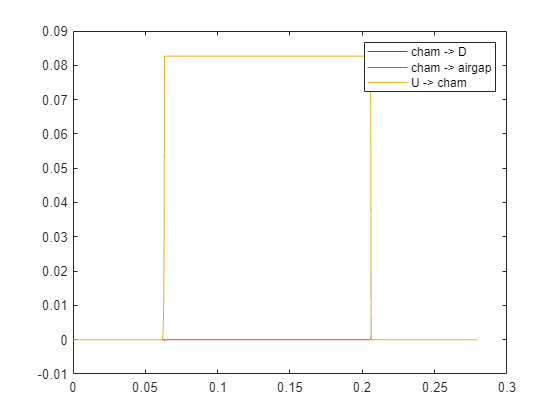

    F = downsample(movmean(F,reduce_factor),reduce_factor);
    F_mag = downsample(movmean(F_mag,reduce_factor),reduce_factor);
    F_spring = downsample(movmean(F_spring,reduce_factor),reduce_factor);
    F_cham = downsample(movmean(F_cham,reduce_factor),reduce_factor);

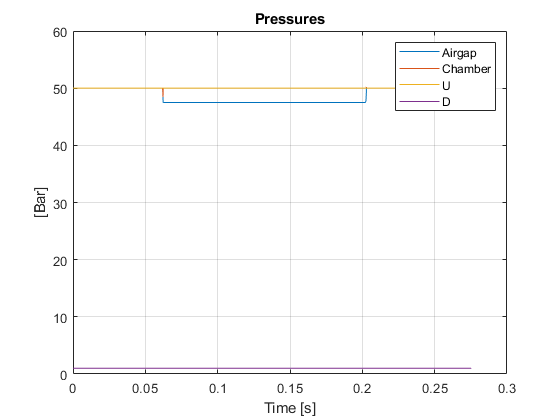

    F_airgap = downsample(movmean(F_airgap,reduce_factor),reduce_factor);
    toc
end

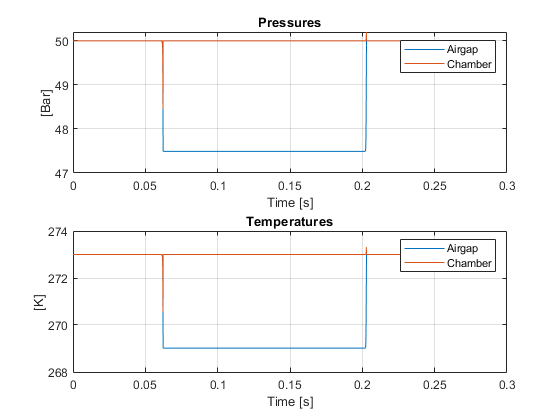

figure()
plot(t,m_dot_cham_d,t,m_dot_cham_airgap,t,m_dot_u_cham)
legend('cham -> D','cham -> airgap','U -> cham')

figure()
plot(t,P_airgap,t,P_cham,t,P_u,t,P_d),legend('Airgap','Chamber','U','D')
title('Pressures'),grid on,xlabel('Time [s]'),ylabel('[Bar]')

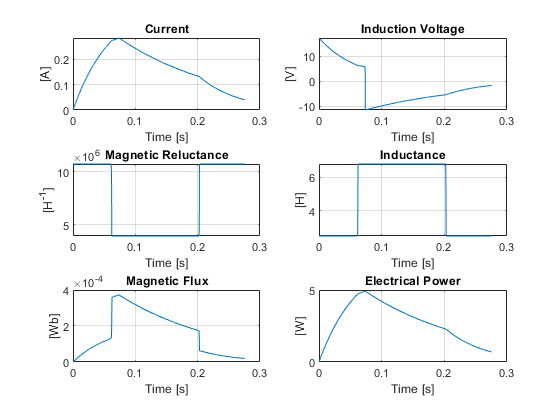

figure()
subplot(2,1,1)
plot(t,P_airgap,t,P_cham),legend('Airgap','Chamber')
title('Pressures'),grid on,xlabel('Time [s]'),ylabel('[Bar]')
subplot(2,1,2)
plot(t,T_airgap,t,T_cham),legend('Airgap','Chamber')
title('Temperatures'),grid on,xlabel('Time [s]'),ylabel('[K]')
figure() 
subplot(3,2,1)
plot(t,current)
title('Current'),grid on,xlabel('Time [s]'),ylabel('[A]')
subplot(3,2,2)
plot(t,voltage_L)
title('Induction Voltage'),grid on,xlabel('Time [s]'),ylabel('[V]')
subplot(3,2,3)
plot(t,MR_total)
title('Magnetic Reluctance'),grid on,xlabel('Time [s]'),ylabel('[H^{-1}]')
subplot(3,2,4)
plot(t,inductance)

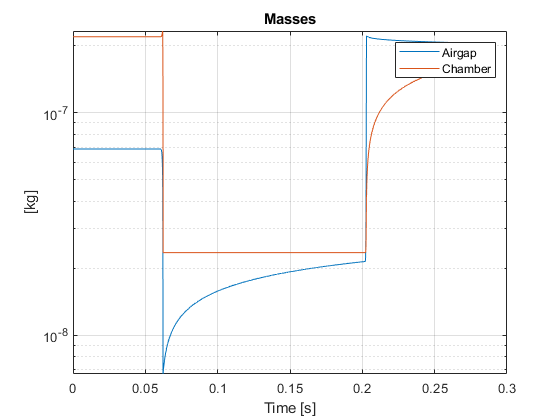

title('Inductance'),grid on,xlabel('Time [s]'),ylabel('[H]')
subplot(3,2,5)
plot(t,flux)

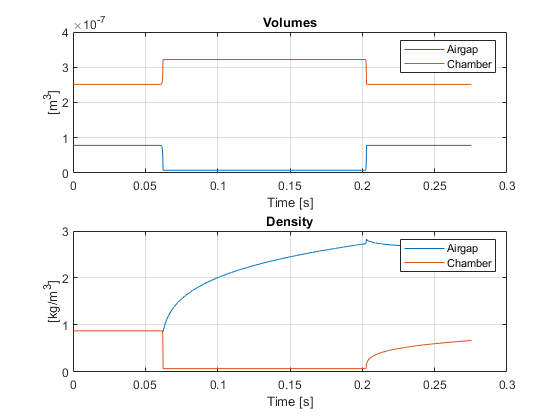

title('Magnetic Flux'),grid on,xlabel('Time [s]'),ylabel('[Wb]')
subplot(3,2,6)
plot(t,current.*Vdd)
title('Electrical Power'),grid on,xlabel('Time [s]'),ylabel('[W]')
figure()
semilogy(t,M_airgap,t,M_cham),legend('Airgap','Chamber')
title('Masses'),grid on,xlabel('Time [s]'),ylabel('[kg]')

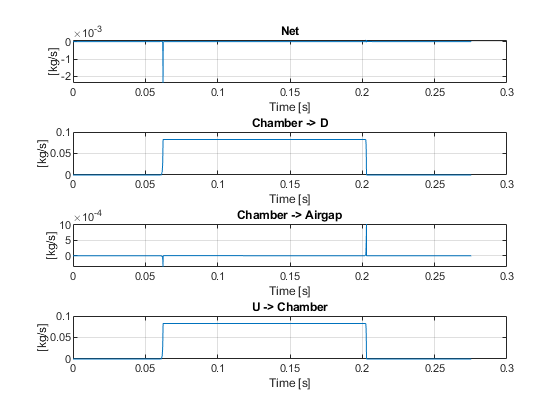

figure()
subplot(2,1,1)
plot(t,Vol_airgap,t,Vol_chamber),legend('Airgap','Chamber')
title('Volumes'),grid on,xlabel('Time [s]'),ylabel('[m^3]')
subplot(2,1,2)
plot(t,M_airgap./Vol_airgap,t,M_cham./Vol_chamber),legend('Airgap','Chamber')
title('Density'), grid on,xlabel('Time [s]'),ylabel('[kg/m^3]')
figure()
subplot(4,1,1)

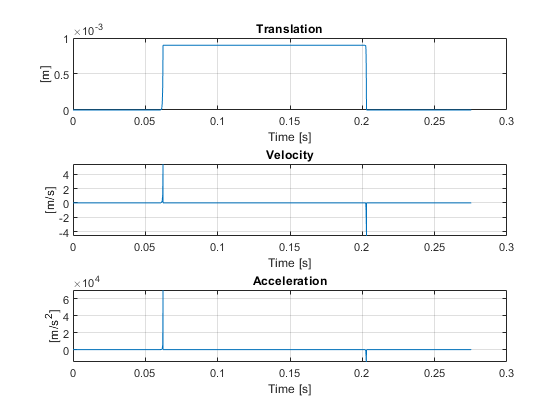

plot(t,m_dot_cham_net),title('Net'),grid on,xlabel('Time [s]'),ylabel('[kg/s]')
subplot(4,1,2)
plot(t,m_dot_cham_d),title('Chamber -> D'),grid on,xlabel('Time [s]'),ylabel('[kg/s]')
subplot(4,1,3)
plot(t,m_dot_cham_airgap),title('Chamber -> Airgap'),grid on,xlabel('Time [s]'),ylabel('[kg/s]')
subplot(4,1,4)
plot(t,m_dot_u_cham),title('U -> Chamber'),grid on,xlabel('Time [s]'),ylabel('[kg/s]')
figure()
subplot(3,1,1)
plot(t,x)

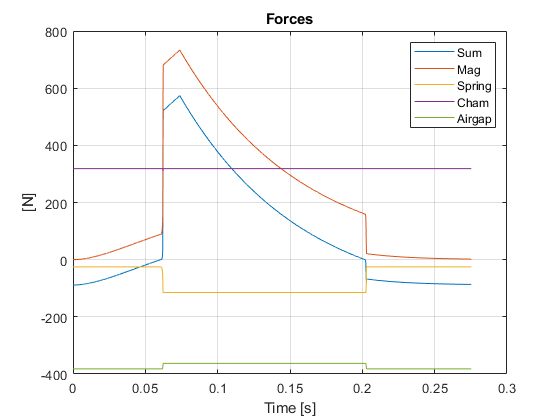

title('Translation'),grid on,xlabel('Time [s]'),ylabel('[m]')
subplot(3,1,2)
plot(t,v)

title('Velocity'),grid on,xlabel('Time [s]'),ylabel('[m/s]')
subplot(3,1,3)
plot(t,a)
title('Acceleration'),grid on,xlabel('Time [s]'),ylabel('[m/s^2]')
figure()
plot(t,F,t,F_mag,t,-F_spring,t,F_cham,t,-F_airgap),legend('Sum','Mag','Spring','Cham','Airgap')
title('Forces'),grid on,xlabel('Time [s]'),ylabel('[N]')